# VENTANAS

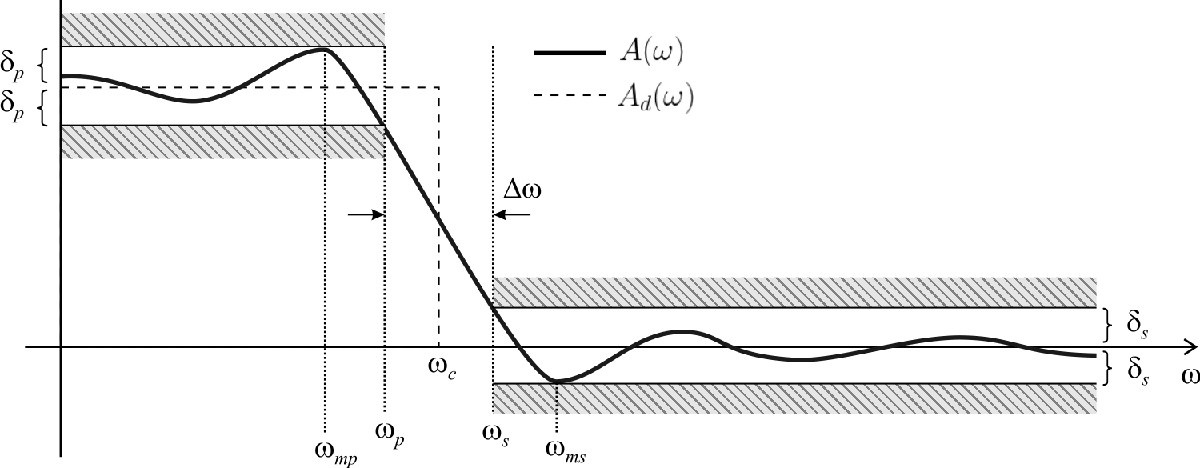

**1) Diseñar un filtro pasa bajos que cumpla con las especificaciones indicadas abajo. Determine la ventana adecuada y el orden que cumplen con las especificaciones.**

**0.9 < |H(w)| < 1.1        0 < |w|< 0.42**$\pi$ 

**|H(w)| < 0.02             0.7**$\pi$** < |w| < 2**$\pi$

clc; clear; close all;

%funcion para crear ventana deseada(un PB antitransformado)
h= @(nm, wc, N)( (wc/pi) .* sinc((wc/pi) .* (nm - N/2)) );

deltaP = 0.1/2; %0.05
dletaS = 0.02; %miro el mas chico, desde la de Hann.
DW = 0.28*pi;
wc= (0.7 + 0.42)*pi/2

wc = 1.7593

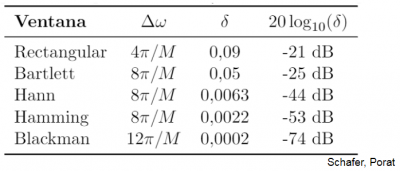

## Hann:[ tengo un deltaS = 0.02 (el mas chico) cumple Hann hacia abajo]

$$\Delta$W
$ : 8$\pi$/$M$  $\delta$= 0,0063.

% Orden del filtro
%%DW = 8*pi/M<-- de aca despejar masomenos el M
%Elijo el orden del filtro.
M= ceil(8*pi/DW)

M = 29

N= M-1

N = 28

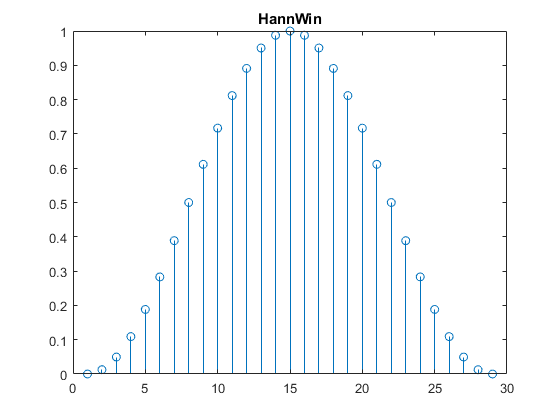


%numero de muestras.
nfft = 8192;
%Vector de frecuencias.
w = linspace(0, 2*pi, nfft);
%Ventanas a Hann.
w4 = window(@hann, N+1)';
%Creo mi filtro PB con la ventana
PB = h(0:N, wc, N);
% FFT del filtro.
W4 = fft(PB.*w4, nfft);

% Respuesta en el tiempo de las ventanas
figure
stem(w4), title('HannWin')%%% xlim([-29 N+30]), ylim([0 1.2])

%%Tiene en cuenta la fase que absorve el modulo, los saltos de pi
[A, w, phi] = zerophase(PB.*w4, 1, w);
hold off;

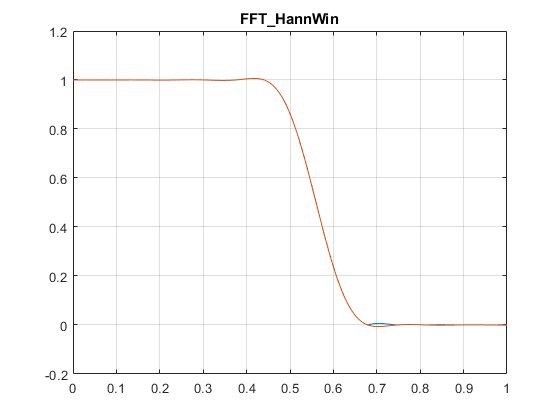

figure()
plot(w/pi,abs(W4)), title('FFT\_HannWin')
hold on
plot(w/pi, A);
xlim([0 1])
grid on;

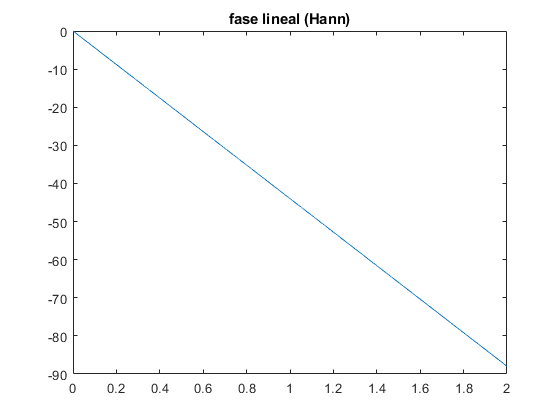


figure()
plot(w/pi, phi)
title("fase lineal (Hann)")

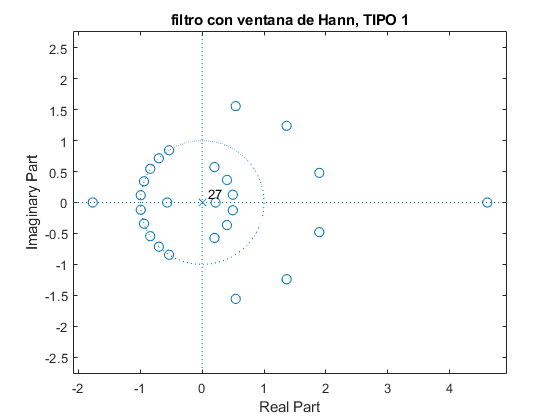


figure()
zplane(PB.*w4,1)
title("filtro con ventana de Hann, TIPO 1")

%es de tipo 1.


# ACTIVIDAD 2: PASA ALTOS FLG.

**1) Diseñar un filtro pasa altos que cumpla con las especificaciones indicadas más abajo. Determine la ventana adecuada y el orden que cumplen con las especificaciones. **

**2) Hallar la expresión de hd [n] e implementarla en Matlab. Graficar |H(𝜔)| para 𝜔 ∈ [0,𝜋) y verificar si se satisfacen las especificaciones. **

**3) Graficar h[n] y el diagrama de polos y ceros. ¿Qué tipo FLG resultó el filtro implementado? **

**4) Modificar el orden N en uno y repetir el punto 3). ¿Se siguen cumpliendo las especificaciones?**

**0.992 < |H(w)| <1.008        0.7 < |w|< **$\pi$

**|H(w)| < 0.001             0 < |w| < 0.5**$\pi$

clc; clear; close all;
deltaP = 0.001; %0.05
dletaS = 0.008; %miro el mas chico, desde la de Hann.

DW = (0.7 - 0.5)*pi;
wc= (0.7 + 0.5)*pi/2;

%Calculo del orden del filtro
M= ceil(12*pi/DW)

M = 61

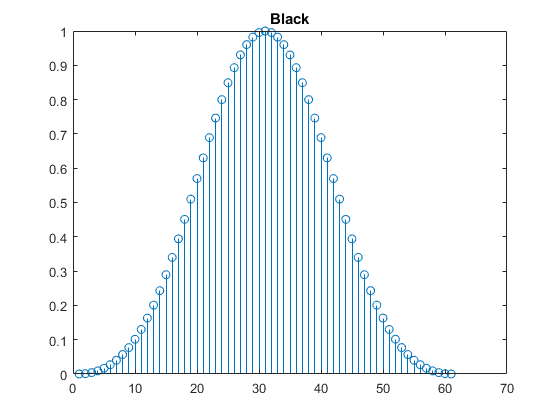

N= M-1;
n= 0:N;

pb= @(nm, wc, N)( (wc/pi) .* sinc((wc/pi) .* (nm - N/2)) );
%ventana deseada.
hd = pb(n, pi, N) - pb(n, wc, N);
%Numero de muestras para frecuencia.
nfft = 8192;

%Ventana de Blackman.
w = linspace(0, 2*pi, nfft);
w5 = window(@blackman, N+1)';
%Ventaneo con Blackman.
h = hd.*w5;

% FFT del ventaneo
W5 = fft(h, nfft);

% Respuesta en el tiempo de las ventanas
figure
stem(w5), title('Black')%%% xlim([-29 N+30]), ylim([0 1.2])

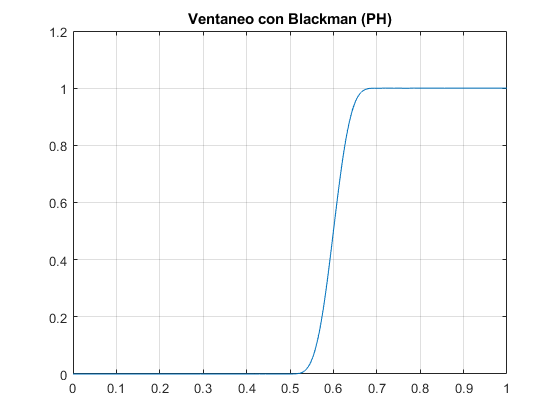


figure
plot(w/pi, abs(W5));
xlim([0 1])
title("Ventaneo con Blackman (PH)")
grid on;

%%Tiene en cuenta la fase que absorve el modulo, los saltos de pi
[A, w, phi] = zerophase(h, 1, w);
hold off;

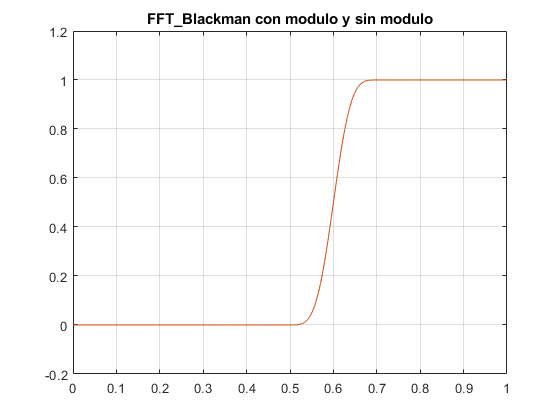


figure()
plot(w/pi, abs(W5)), title('FFT\_Blackman con modulo y sin modulo')
hold on
plot(w/pi, A);
xlim([0 1])
grid on;

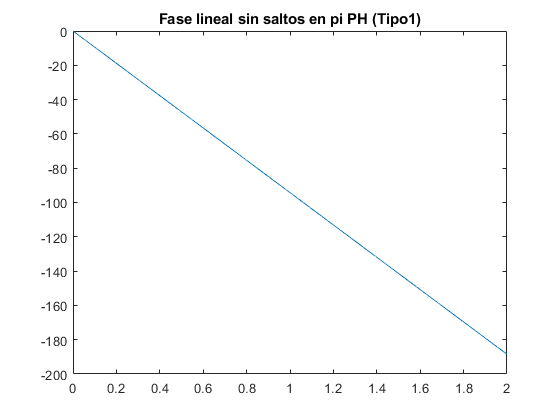


figure()
plot(w/pi, phi); title("Fase lineal sin saltos en pi PH (Tipo1)");

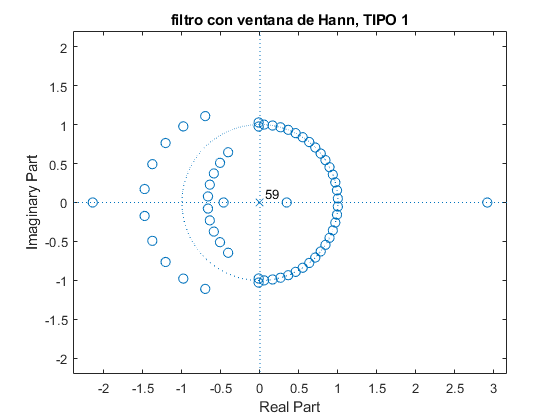


figure()
zplane(h, 1)
title("filtro con ventana de Hann, TIPO 1")

%es de tipo 1.

%Calculo del orden del filtro
M= ceil(12*pi/DW)

M = 61

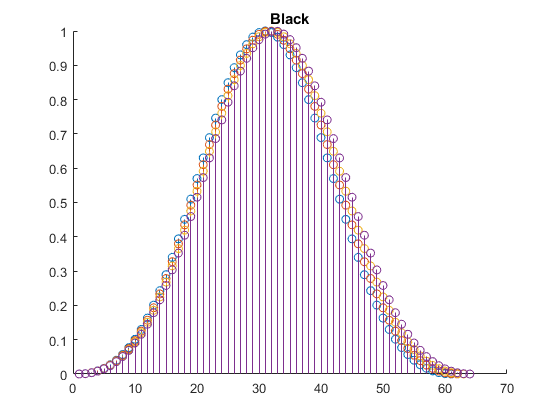

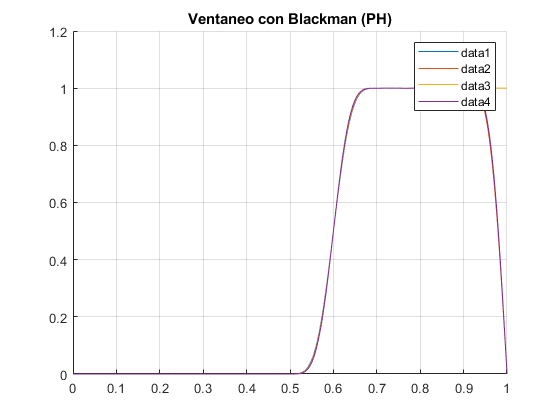

pb= @(nm, wc, N)( (wc/pi) .* sinc((wc/pi) .* (nm - N/2)) );

for N= [M-1 , M, M+1 M+2]
    
    n= 0:N;  
    %ventana deseada.
    hd = pb(n, pi, N) - pb(n, wc, N);
    %Numero de muestras para frecuencia.
    nfft = 8192;
    
    %Ventana de Blackman.
    w = linspace(0, 2*pi, nfft);
    w5 = window(@blackman, N+1)';
    %Ventaneo con Blackman.
    h = hd.*w5;
    
    % FFT del ventaneo
    W5 = fft(h, nfft);
    
    % Respuesta en el tiempo de las ventanas
    figure(10)
    hold on
    stem(w5), title('Black')%%% xlim([-29 N+30]), ylim([0 1.2])
    hold off;
    
    figure(11)
    hold on
    plot(w/pi, abs(W5));
    xlim([0 1])
    title("Ventaneo con Blackman (PH)")
    legend
    grid on;
    hold off;
    

end

Notar que con N= M-1 y con N= M+1 ( en estos casos M=61->M={60, 62}) es decir con orden par, el filtro sigue siendo de tipo 1 y asi puede seguir siendo posible lograr el pasa altos, de otra forma como con N= M o N= M+2 el orden es impar y el filtro no puede ser de tipo 1, entonces no es posible formar el pasa altos deseado, el orden del filtro es muy importante a la hora de diseñar polos.

## **Actividad 3**

**1) Diseñar un filtro pasa banda que cumpla con las especificaciones indicadas más abajo. **

**a) Utilice una ventana de Kaiser y determine el parámetro 𝛽 y el orden N para cumplir con las especificaciones. **

**b) Implementar el filtro en Matlab. Graficar A(𝜔) y verificar si se satisfacen las especificaciones. ¿Qué tipo FLG resultó el filtro implementado?**

**               |H(w)| **$\leq$** 0,09                       0 **$\leq$** |w| **$\leq$** 0,24**$\pi$

**    0,9 **$\leq$**  |H(w)| **$\leq$ 1,1**               0,28 **$\pi$ $\leq$** |w| < 0.6**$\pi$

**               |H(w)| **$\leq$**0,03                     0,7 **$\leq$** |w| < **$\pi$

**2) Graficar en un mismo plot() A(𝜔) para los filtros pasa bajos definidos por N=50, 𝜔 c =0.5𝜋 y 𝛽 = {0; 1; 2; 3; 4}. Observe el máximo ripple en función del parámetro 𝛽.**

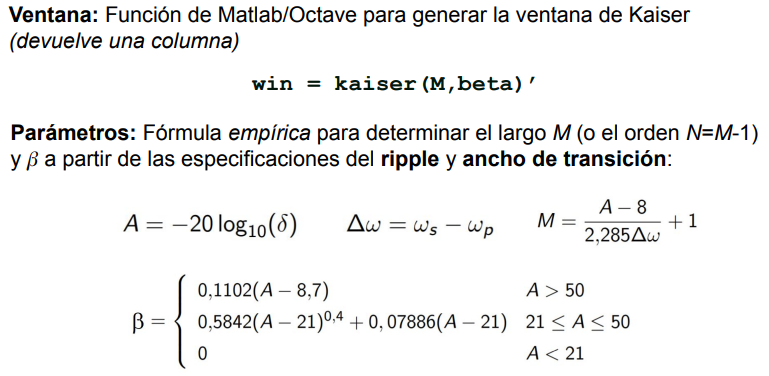

x=sym('x','real');
deltaS1 = 0.09;
deltaP = 0.1;   
deltaS2 = 0.03;       %deltaS2 es la menor.

Dw_1= (0.28 - 0.24)*pi;
Dw_2= (1 - 0.7)*pi;  %Dw_2 = 0.3 es la menor.

wc_1 = (0.28 + 0.24)*pi/2;
wc_2 = (0.6 + 0.7)*pi/2;

%Obtengo el ripplle y el Dw mas chico para cumplir las especificaciones
ripple = deltaS2;
Dw= Dw_1

Dw = 0.1257


%Obtengo los parametros de Kaiser.
A= -20*log10(ripple)

A = 30.4576

M = ceil( (A-8)/(2.285*Dw) + 1)

M = 80

N= M-1;
nm= 0:N;

%Funcion para calcular Beta
fBeta = piecewise(x > 50,       0.1102*(x-8.7), ...
        (21<= x) & (x <= 50), 0.5842*(x-21)^0.4 + 0.07886*(x-21), ...
                x < 21,        0)

$$fBeta = \left\{ \begin{array}{cl} \frac{551\,x}{5000}-\frac{47937}{50000} & \text{ if }50<x\\ \frac{3943\,x}{50000}+\frac{2921\,{\left(x-21\right)}^{2/5}}{5000}-\frac{82803}{50000} & \text{ if }x\in \left[21,50\right]\\ 0 & \text{ if }x<21 \end{array}\right.$$

%Beta.
Beta = double(subs(fBeta, x,A))

Beta = 2.1809


%filtro deseado. 
%hd==PasaBanda = PasaAll-PL-PH = PA - PL1 - (PA-PL2)= -PL1+PL2
hd = -pb(nm, wc_1, N) + pb(nm, wc_2, N);


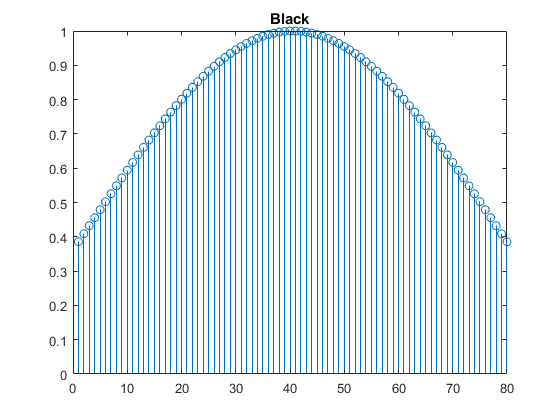

%Numero de muestras para frecuencia.
nfft = 8192;

%Ventana de Blackman.
w = linspace(0, 2*pi, nfft);
%wk = window(@blackman, N+1)';
wk = kaiser(N+1, Beta)';
%Ventaneo con Kaiser.
h = hd.*wk;

% FFT del ventaneo
Wk = fft(h, nfft);

% Respuesta en el tiempo de las ventanas
figure
stem(wk), title('Black')%

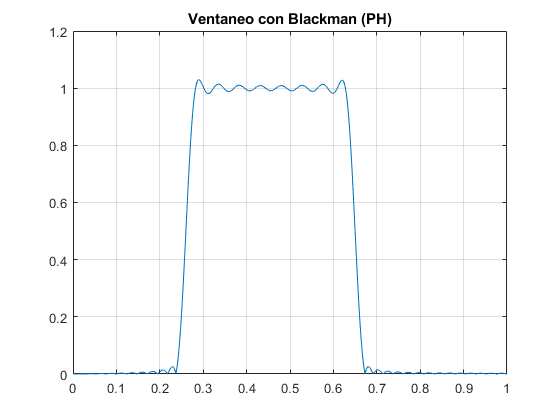


figure
plot(w/pi, abs(Wk));
xlim([0 1])
title("Ventaneo con Blackman (PH)")
grid on;

%%Tiene en cuenta la fase que absorve el modulo, los saltos de pi
[A, w, phi] = zerophase(h, 1, w);
hold off;

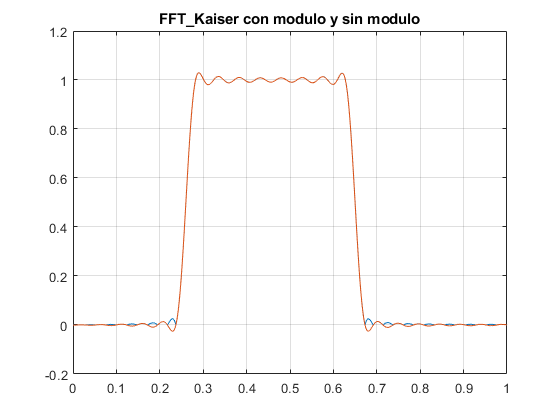


figure()
plot(w/pi, abs(Wk)), title('FFT\_Kaiser con modulo y sin modulo')
hold on
plot(w/pi, A);
xlim([0 1])
grid on;

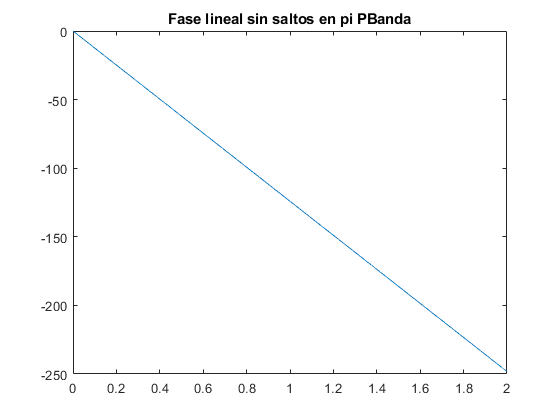


figure()
plot(w/pi, phi); title("Fase lineal sin saltos en pi PBanda");

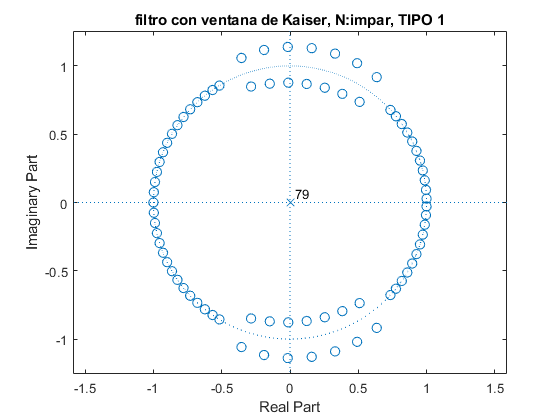


figure()
zplane(h, 1)
title("filtro con ventana de Kaiser, N:impar, TIPO 1")

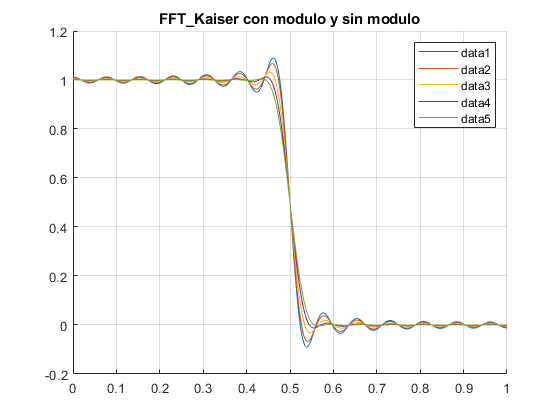

N= 50;
wc= 0.5*pi;
nm= 0:N;
%filtro deseado. 
hd = pb(nm, wc, N);
%Numero de muestras para frecuencia.
nfft = 8192;  
%Ventana de Blackman.
w = linspace(0, 2*pi, nfft);

for Beta = [0, 1, 2, 3, 4]    
    
    wk_ = kaiser(N+1, Beta)';
    %Ventaneo con Blackman.
    h = hd.*wk_;
    
    % FFT del ventaneo
    %Wk = fft(h, nfft);
    
    %%Tiene en cuenta la fase que absorve el modulo, los saltos de pi
    [A, w, phi] = zerophase(h, 1, w);
    hold off;
    
    figure(20)
    hold on
    plot(w/pi, A), title('FFT\_Kaiser con modulo y sin modulo')
    xlim([0 1])
    legend()
    grid on;
    hold off
end

A medida que se aumenta Beta, el ripple disminuye pero el ancho de banda aumenta, son inversamente proporcionales.

## **Actividad 4**

**equiriple: **[https://youtu.be/Qx_kFehW8TI?t=1205](https://youtu.be/Qx_kFehW8TI?t=1205)

**1) Implementar un filtro pasa bajos utilizando el método de diseño óptimo Equiripple. Grafique h(n), |H(𝜔)| y el diagrama de polos y ceros. Nota: para obtener el orden, utilice la la aproximación de Kaiser y luego vaya modificando el orden hasta cumplir con la especificación.**

** 2) Grafique la función amplitud A(𝜔) y verifique experimentalmente si se cumple el teorema de las alternancias.**

**    0,96 **$\leq$** | H(w) | **$\leq$**1,04                  0 **$\leq$** | w | **$\leq$** 0,45 **$\pi$

**                | H(w) | **$\leq$** 0,1              0,5**$\pi$ $\leq$** |w| **$\leq$ $\pi$

w = linspace(0, 2*pi, nfft);

deltaP= 0.04;
deltaS= 0.1;

Dw= (0.5 - 0.45)*pi;
wc= (0.5 + 0.45)*pi/2;

%Aproximacion del orden:
M_= @(delta1, delta2, Df)( (-20*log10(sqrt(delta1*delta2)) - 13) / (14.6*Df) + 1);
M = ceil( M_(deltaP, deltaS, Dw/(2*pi)) );
N= M-1

N = 31

N = N + 7

N = 38

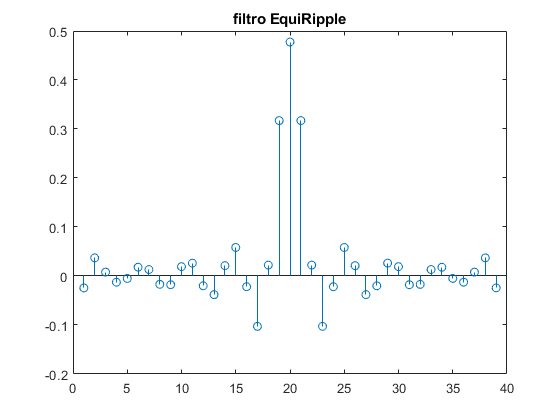

f1 = 0.45; %/(2*pi)
f2 = 0.5; %/(2*pi);

f = [0 f1 f2 1];
a = [1 1 0 0];
v = [1/(deltaP), 1/(deltaS)];
%Filtro Equiripple.
EquiRP = firpm(N, f, a, v);

fftEqRP= fft(EquiRP, nfft);

%grafico h(n)
stem(EquiRP)
title("filtro EquiRipple")

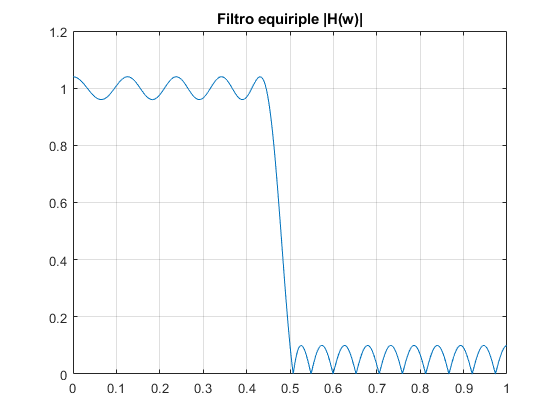


%grafico |H(w)|
figure()
plot(w/pi, abs(fftEqRP))
title("Filtro equiriple |H(w)|")
grid on;
xlim([0, 1])

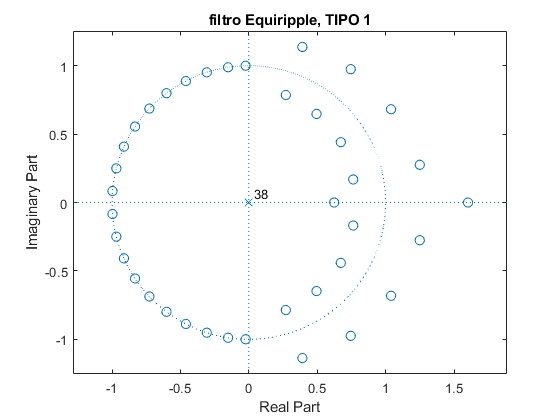


%grafico polos y ceros.
figure()
zplane(EquiRP, 1)
title("filtro Equiripple, TIPO 1")

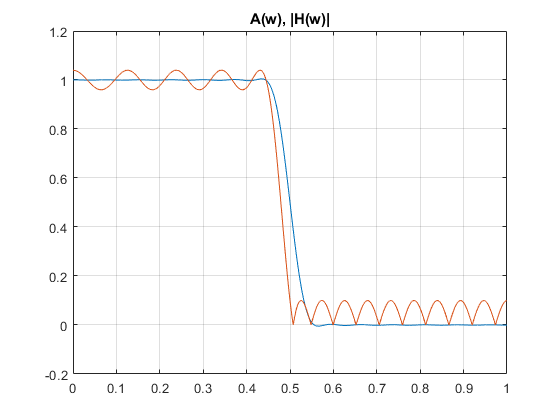

%Item 2
[A, w, phi] = zerophase(h, 1, w);

figure()
plot(w/pi, A)
hold on
plot(w/pi, abs(fftEqRP))
title("A(w), |H(w)|")
grid on
xlim([0 1])


% para verificar el teorema de alternancias 
[TF_m,P_m]= islocalmin(A);
[TF_M,P_M]= islocalmax(A);

r = (length(P_m(TF_m)) + length(P_m(TF_m))) + 2

r = 52

L = (N)/2  %es tipo I, N:par, M:impar

L = 19